## Homework 1

**2411374 朱灏轩**

### Question 1

理想的P-N结电流方程为：


$$I=I_c(e^{\frac{qV}{k_0T}}-1.0)$$


其中，$I$为电流，$V$为偏压，$T$为温度，$I_c$为反向饱和电流，$q
$为电子电荷，$k_0$为玻尔兹曼常数。

在存在内在电阻的情况下，P-N结的电流方程变为：


$$I=I_c(e^{\frac{q(V-I\times R)}{k_0T}}-1.0)$$


其中$R$为P-N结的内在电阻。

采用牛顿法解含内阻的P-N结电流方程


$$I=I_c(e^{\frac{q(V-I\times R)}{k_0T}}-1.0)$$


其中，$Ic=10^{-11}\ \text{A} \\
R=10\ \Omega \\
T=300\ \text{K}$

在$V=[-1, 1]\ \text{V}$的区间内每间隔$0.01\ \text{V}$求解对应的电流值，要求相对精度达到$0.001$。用对数尺度画出求得的$I-V$数据，并在适当的区间上与理想电流方程作比较。

### Solution

首先根据题设信息在程序中设定相关变量

% 参数设置
I_c = 1e-11; % 理想电流
R = 10; % 内阻
T = 300; % 温度
k_0 = physconst("Boltzmann"); % 玻尔兹曼常数
q = 1.602176634e-19; % 电子带电量
Vmin = -1;
Vmax = 1;
V = Vmin:0.01:Vmax;
I = zeros(size(V)); % 创建电流数组
delta = 0.001; % 定义相对精度
i_init = 0; % 定义电流初始值

遍历电压数组，根据牛顿法解出含内阻情况下的电流变化情况

% 在含内阻情况下求解方程
syms x; % 定义未知数x
index = 1;
for v = Vmin:0.01:Vmax
    f(x) = I_c * (exp(q*(v - x*R)/(k_0*T)) - 1.0) - x; % 定义待求解方程
    df = diff(f, x); % 求函数对未知数x的导数
    i_curr = i_init; % 设定电流初始值
    while true
        i_next = i_curr - double(f(i_curr))/double(df(i_curr)); % 计算下一个迭代值
        if abs((i_next - i_curr)/i_next) < delta % 设定迭代终止条件
            break;
        elseif i_next == 0 % 若i_next为0则停止迭代
            break;
        end
        i_curr = i_next;
    end
    I(index) = i_curr; % 保存数值解
    index = index + 1;
end

类似地，求出不含内阻的理想情况下，电流的变化情况

% 在不含内阻的理想情况下求解方程
I_ideal = zeros(size(V));
syms x; % 定义未知数x
index = 1;
for v = Vmin:0.01:Vmax
    f(x) = I_c * (exp(q*(v)/(k_0*T)) - 1.0) - x; % 定义待求解方程
    df = diff(f, x); % 求函数对未知数x的导数
    i_curr = i_init; % 设定电流初始值
    iter = 0;
    while true
        i_next = i_curr - double(f(i_curr))/double(df(i_curr)); % 计算下一个迭代值
        if abs((i_next - i_curr)/i_next) < delta % 设定迭代终止条件
            break;
        elseif i_next == 0 % 若i_next为0则停止迭代
            break;
        end
        i_curr = i_next;
        iter = iter + 1;
    end
    I_ideal(index) = i_curr; % 保存数值解
    index = index + 1;
end

调用`semilogy`命令绘制两种情况下的电流对数图像

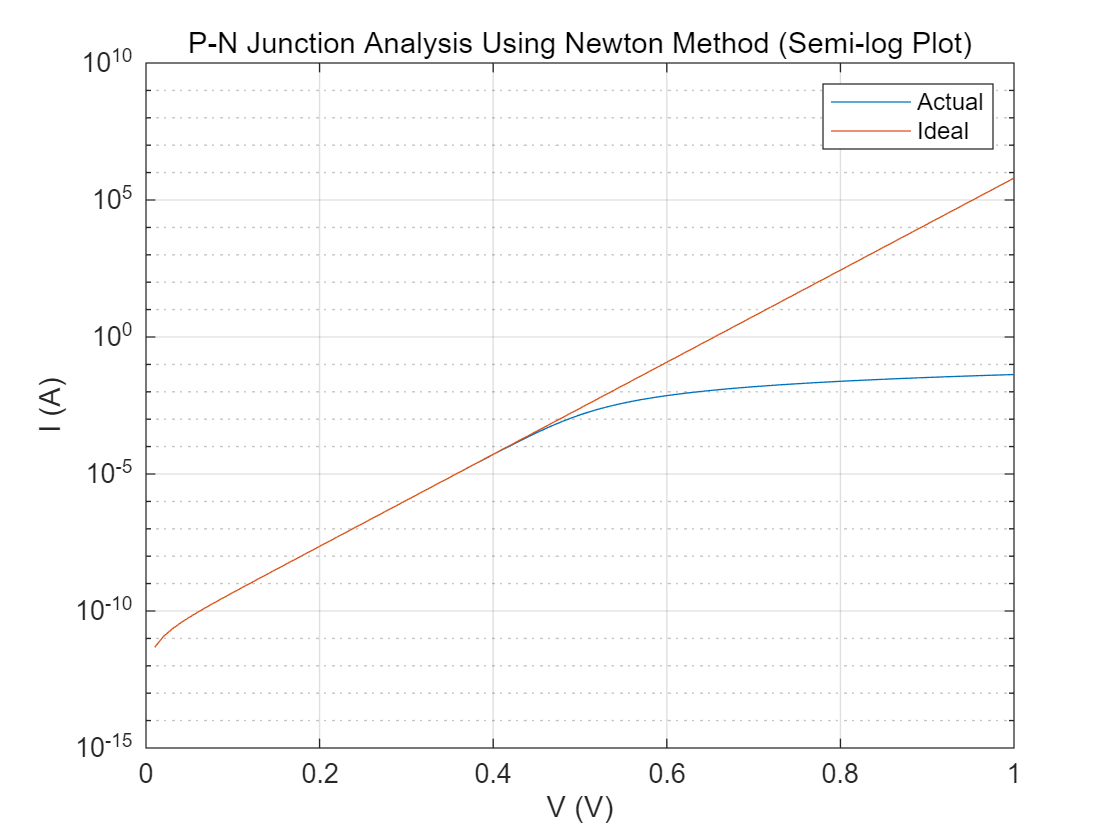

figure;
semilogy(V, I);
hold on;
semilogy(V, I_ideal);
grid on;
xlabel("V (V)");
ylabel("I (A)");
legend("Actual", "Ideal");
title("P-N Junction Analysis Using Newton Method (Semi-log Plot)");
hold off;

上述图像中，绘制了含$10\ \Omega$内阻的PN结的电压电流变化曲线。需要注意的是，由于使用了`semilogy`绘制对数关系图像，导致程序自动忽略负数解。为了能够观察$[-1, 1]\ \text{V}$范围内的电压电流变化曲线，使用`plot`绘制电流变化曲线。

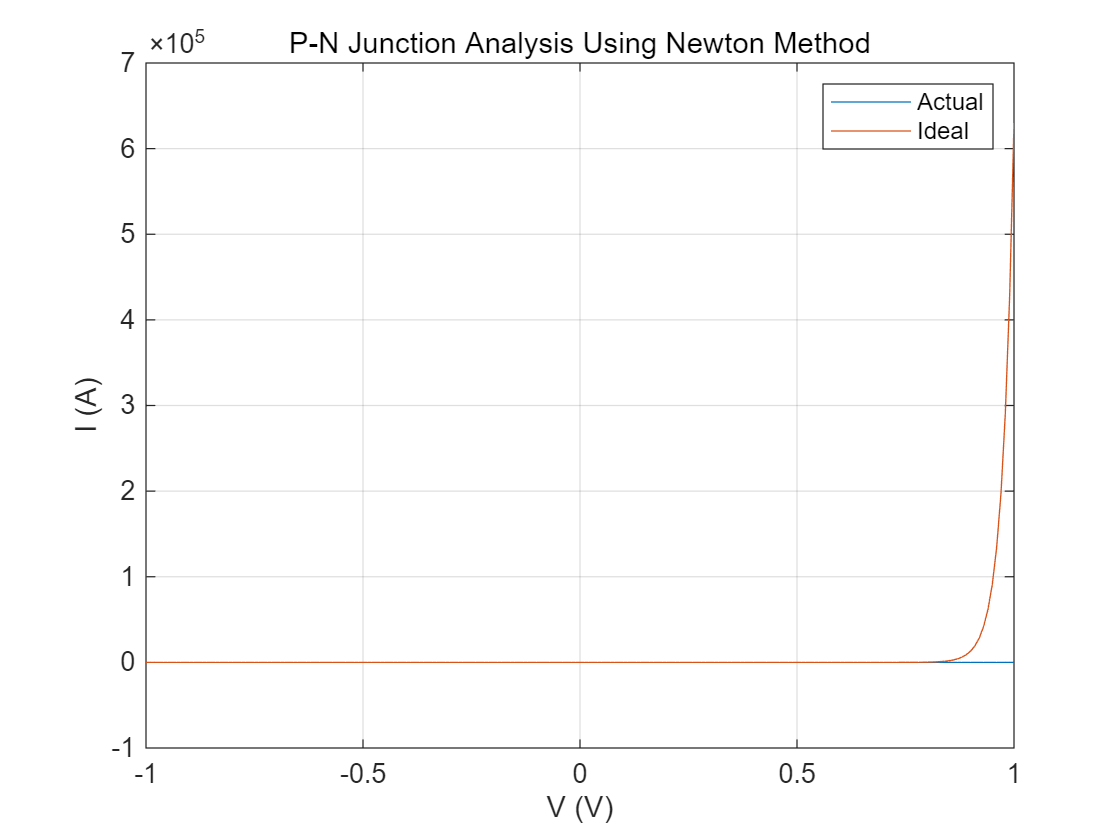

figure;
plot(V, I);
hold on;
plot(V, I_ideal);
grid on;
xlabel("V (V)");
ylabel("I (A)");
legend("Actual", "Ideal");
title("P-N Junction Analysis Using Newton Method");
hold off;

尝试使用不动点法，求解含内阻情况下的电流方程，调用`fzero`命令

i_fzero = zeros(size(V)); % 创建新电流数组
index = 1;
for v = Vmin:0.01:Vmax
    % 定义待求解函数
    fun = @(x) I_c * (exp(q*(v - x*R)/(k_0*T)) - 1.0) - x;
    x0 = 0.0; % 定义初始值
    root = fzero(fun, x0); % 调用fzero求解方程
    i_fzero(index) = root;
    index = index + 1;
end

同样采用不动点法，求解理想情况下的电流方程

i_fzero_ideal = zeros(size(V));
index = 1;
for v = Vmin:0.01:Vmax
    % 定义待求解函数
    fun_ideal = @(x) I_c * (exp(q*(v)/(k_0*T)) - 1.0) - x;
    x0 = 0.0; % 定义初始值
    root = fzero(fun_ideal, x0); % 调用fzero求解方程
    i_fzero_ideal(index) = root;
    index = index + 1;
end

上述代码通过调用`fzero`得到了另一个电流值数组，使用`semilogy`以及`plot`绘制电流变化曲线

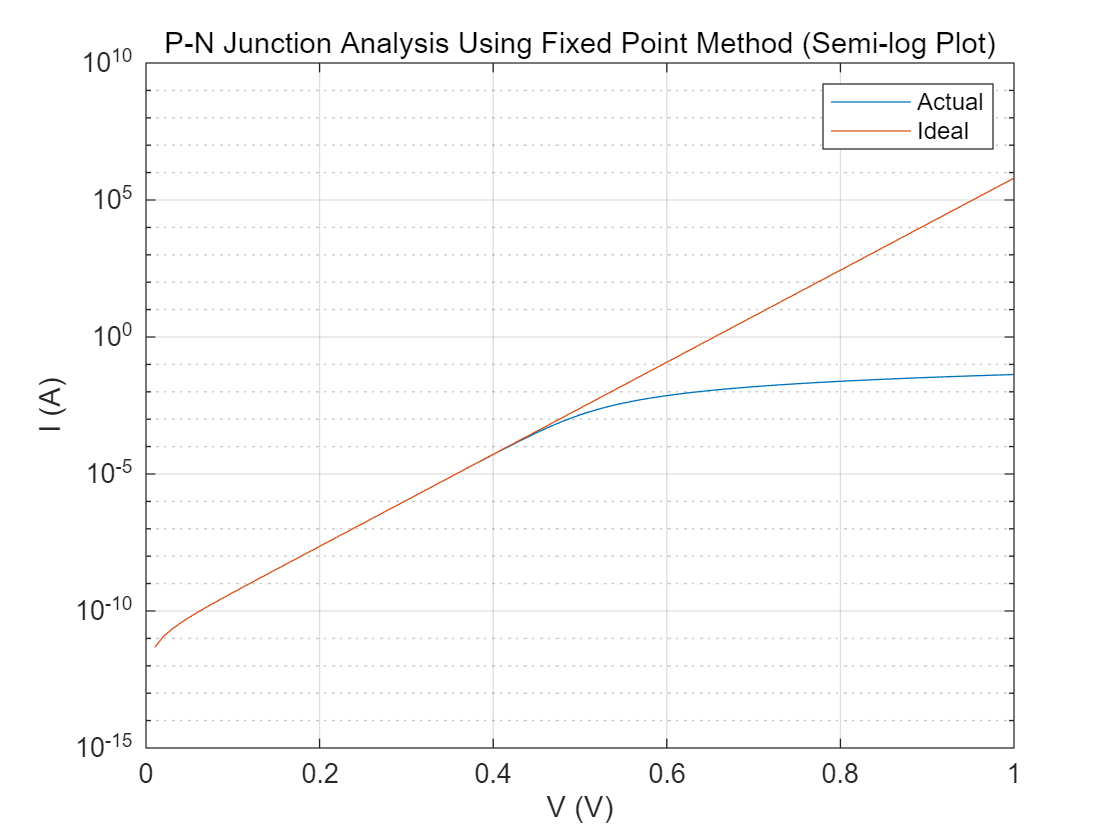

% 调用semilogy
figure;
semilogy(V, i_fzero);
hold on;
semilogy(V, i_fzero_ideal);
grid on;
xlabel("V (V)");
ylabel("I (A)");
legend("Actual", "Ideal");
title("P-N Junction Analysis Using Fixed Point Method (Semi-log Plot)");
hold off;

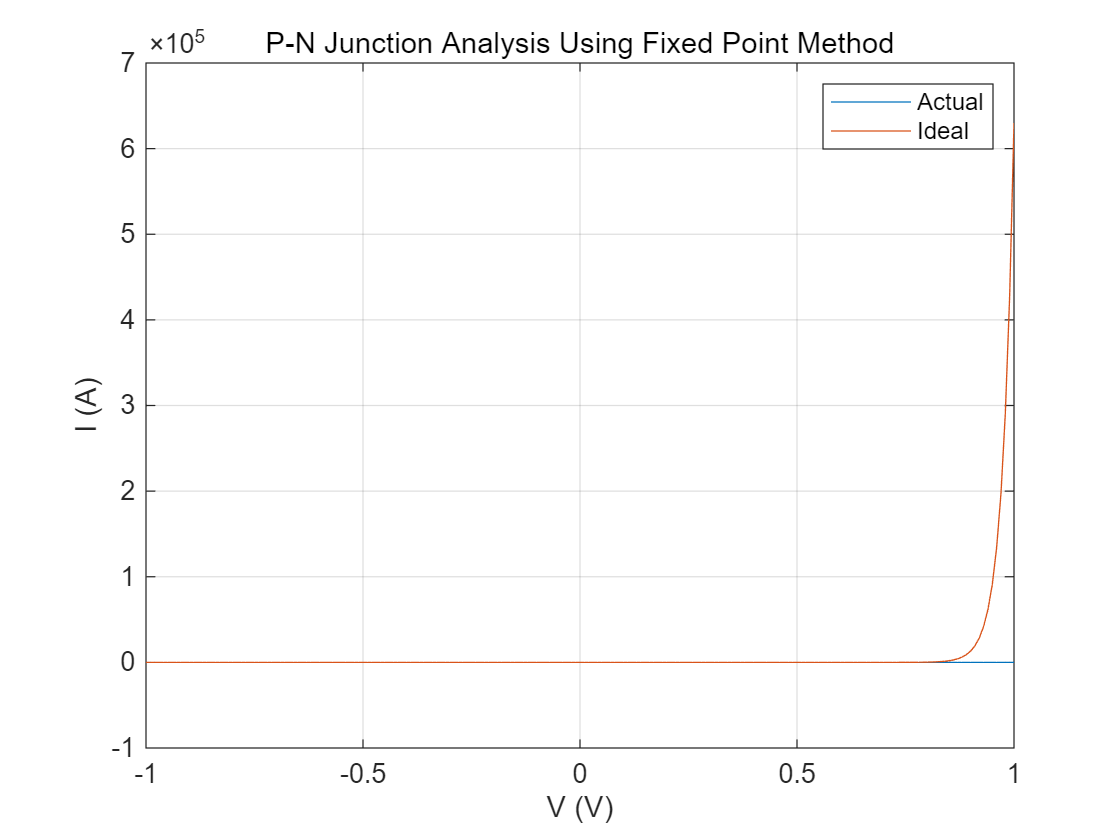

% 调用plot
figure;
plot(V, i_fzero);
hold on;
plot(V, i_fzero_ideal);
grid on;
xlabel("V (V)");
ylabel("I (A)");
legend("Actual", "Ideal");
title("P-N Junction Analysis Using Fixed Point Method");
hold off;

比较上述图像可知，使用牛顿法和不动点法求得的数值解相符。

### Question 2

开普勒行星运动轨迹定律：

- 行星绕太阳运动的轨道都是椭圆（ellipse），太阳处在椭圆的一个焦点（focus）上。

- 行星与太阳的连线在相同时间间隔扫过相等的面积。

- 行星轨道的半长轴的三次方跟公转周期的二次方的比值都相等：$a^3/T^2=\text{const}$。（不同行星轨迹之间的联系）

#### Kepler第一定律

行星绕太阳运动的轨道都是椭圆，太阳处在椭圆的一个焦点上。

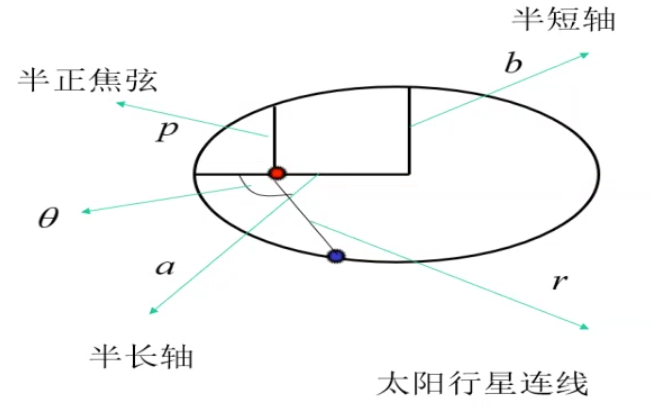

离心率（eccentricity）：$\varepsilon=\sqrt{\frac{a^2-b^2}{a^2}}$

太阳行星连线长度：$r=\frac{p}{1+\varepsilon\cdot\cos\theta}$

#### Kepler第二定律

行星与太阳的连线在相同时间间隔扫过相等的面积。

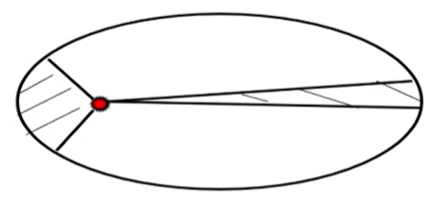


$$\Delta A\propto\Delta t$$



$$\frac{\Delta A}{A}=\frac{\Delta t}{P}$$


其中$A$为椭圆面积，$P$为轨道周期。

求解Kepler方程：$\left\lbrace \begin{array}{l}
r=r\left(t\right)\\
\theta =\theta \left(t\right)
\end{array}\right.$    或者    $\left\lbrace \begin{array}{l}
x=x\left(t\right)\\
y=y\left(t\right)
\end{array}\right.$

- 定义$\frac{\Delta A}{A}=\frac{\Delta t}{P}=\frac{M}{2\pi}$

- 
$$M=E-\varepsilon\cdot\sin E$$


- 
$$\tan\frac{\theta}{2}=\sqrt{\frac{1+\varepsilon}{1-\varepsilon}}\cdot\tan\frac{E}{2}$$


- 
$$r=\frac{p}{1+\varepsilon\cdot\cos\theta}$$


求解顺序：$\Delta t\to M\to E\to \theta \to r$

已知：$\varepsilon=0.7$    $p=1.1$

采用不动点迭代法，以相对精度$0.001$求$\theta$。

### Solution

根据题设条件设定程序参数

% 设定程序参数
M = linspace(0, 2*pi, 50);
epsilon = 0.7;
p = 1.1;
delta = 1e-3; % 相对精度

由$M=E-\varepsilon\cdot\sin E$，求各$M$值对应的$E$

% 根据M求E
E = zeros(size(M)); % 创建E数组
index = 1; % 初始化索引
func_M_E = @(m, e) e - epsilon * sin(e) - m;
for m = M
    func = @(e) func_M_E(e, m);
    % 不动点法开始
    e0 = 0; % E初始值
    % 不动点法迭代
    while true
        e = func(e0);
        if abs((e - e0) / e) < delta % 相对精度条件
            root = e0;
            break;
        elseif e == 0 % 考虑除数为零情况
            root = e0;
            break;
        end
        e0 = e;
    end
    E(index) = root; % 存储数值解
    index = index + 1;
end

根据$\tan\frac{\theta}{2}=\sqrt{\frac{1+\varepsilon}{1-\varepsilon}}\cdot\tan\frac{E}{2}$，有$\theta=2\cdot\arctan\Bigg(\sqrt{\frac{1+\varepsilon}{1-\varepsilon}}\cdot\tan\frac{\mathrm{E}}{2}\Bigg)$，求得各$M$对应的$\theta$

% 根据M求Theta
Theta = 2 * atan(sqrt((1+epsilon)/(1-epsilon)) * tan(E / 2));

由$r=\frac{p}{1+\varepsilon\cdot\cos\theta}$，求每个$\theta$对应的$r$

% 根据Theta求R
R = p ./ (1+epsilon*cos(Theta));

极坐标与直角坐标存在下列对应关系：


$$x=r\cdot\cos\theta$$
    
$$y=r\cdot\sin\theta$$


根据该关系，可将极坐标下的$\theta$与$r$转换为直角坐标下的$x$和$y$

% 坐标转换
x = R .* cos(Theta);
y = R .* sin(Theta);

根据上述直角坐标信息，调用`plot`绘制轨迹

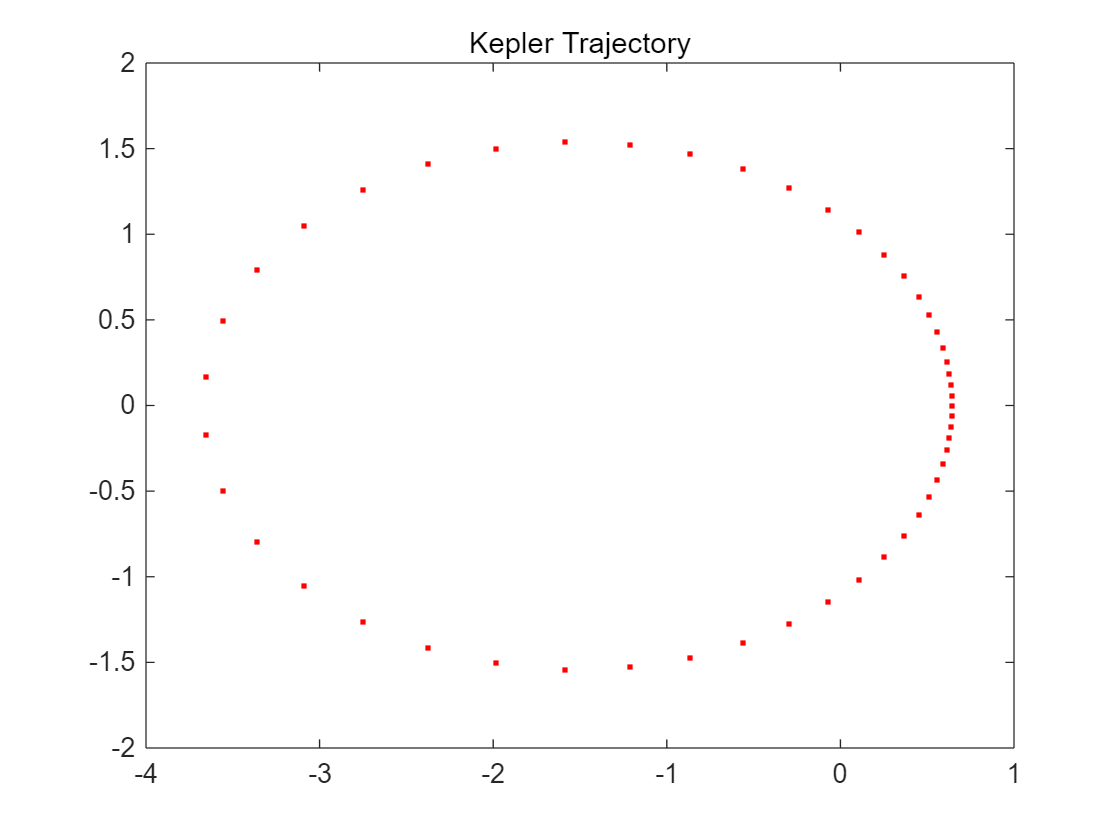

figure;
plot(x, y, "r.");
title("Kepler Trajectory");